# Estimate fascicle strain from Ultrasound B-mode images

## Overview

This MATLAB program estimates muscle fascicle strain from ultrasound B-mode videos by tracking multiple feature points within a user-defined region of interest (ROI).

The algorithm combines feature tracking, principal component analysis (PCA), and geometric projection to compute continuous strain time-series and visualize deformation dynamics.

## Usage

- Prepare an ultrasound B-mode video file (`.mp4 or .avi`).

- Set the correct file paths for `videoDir` and `videoReader` in the MATLAB script.

- Run the script.

- On the first frame, select the region of interest (ROI) using the ellipse tool.

- Fine-tune the ROI and double-click to confirm.

- Choose whether to export the tracking video.

- The program automatically computes fascicle strain and saves the results in the `Results` folder.

## Output

- `TrackElongation_*.mp4`→ Video showing tracked feature points and principal strain direction.

- `results.mat`→ Time-series strain data (`timeSeriesStrain`).

##  Requirements

- MATLAB R2022b or later

- **Toolboxes**

-     Computer Vision Toolbox

-     Image Processing Toolbox

-     Statistics and Machine Learning Toolbox

clear, close

## video import

% Specify the directory and the video file name
videoDir = 'G:\MyDrive\MyMATLAB\sub_data_nerve\No1';
cd(videoDir)
videoReader = VideoReader("G:\MyDrive\MyMATLAB\sub_data_nerve\No1\No1_cont_fast_1.mp4");

% Get video file name
filename = videoReader.Name;

% Design image filter
h = fspecial('average',3);

% Add directories and functions
addpath G:\MyDrive\MyMATLAB\  % for getEchoImgInfo function

% Define analysis range
nFrame = videoReader.NumFrames;
FrameRate = videoReader.FrameRate;

% Extract the first frame of the video
vFirst = readFrame(videoReader);
mag = 1080/size(vFirst,1)*100;  % Scale factor for displaying the image with height 1080 pixels

%% Set scale (convert pixels to millimeters)
figure("Visible","on")

% Display the image with 1080 × 1920 resolution
imshow(vFirst, 'InitialMagnification', mag);

% Display with 16:9 aspect ratio
pbaspect([16 9 1]);

% Compute echo image area and pixel size
[imgInfo, PixelSize, selectDepth] = getEchoImgInfo(vFirst);  % original function


## Specify region of interest (ROI)

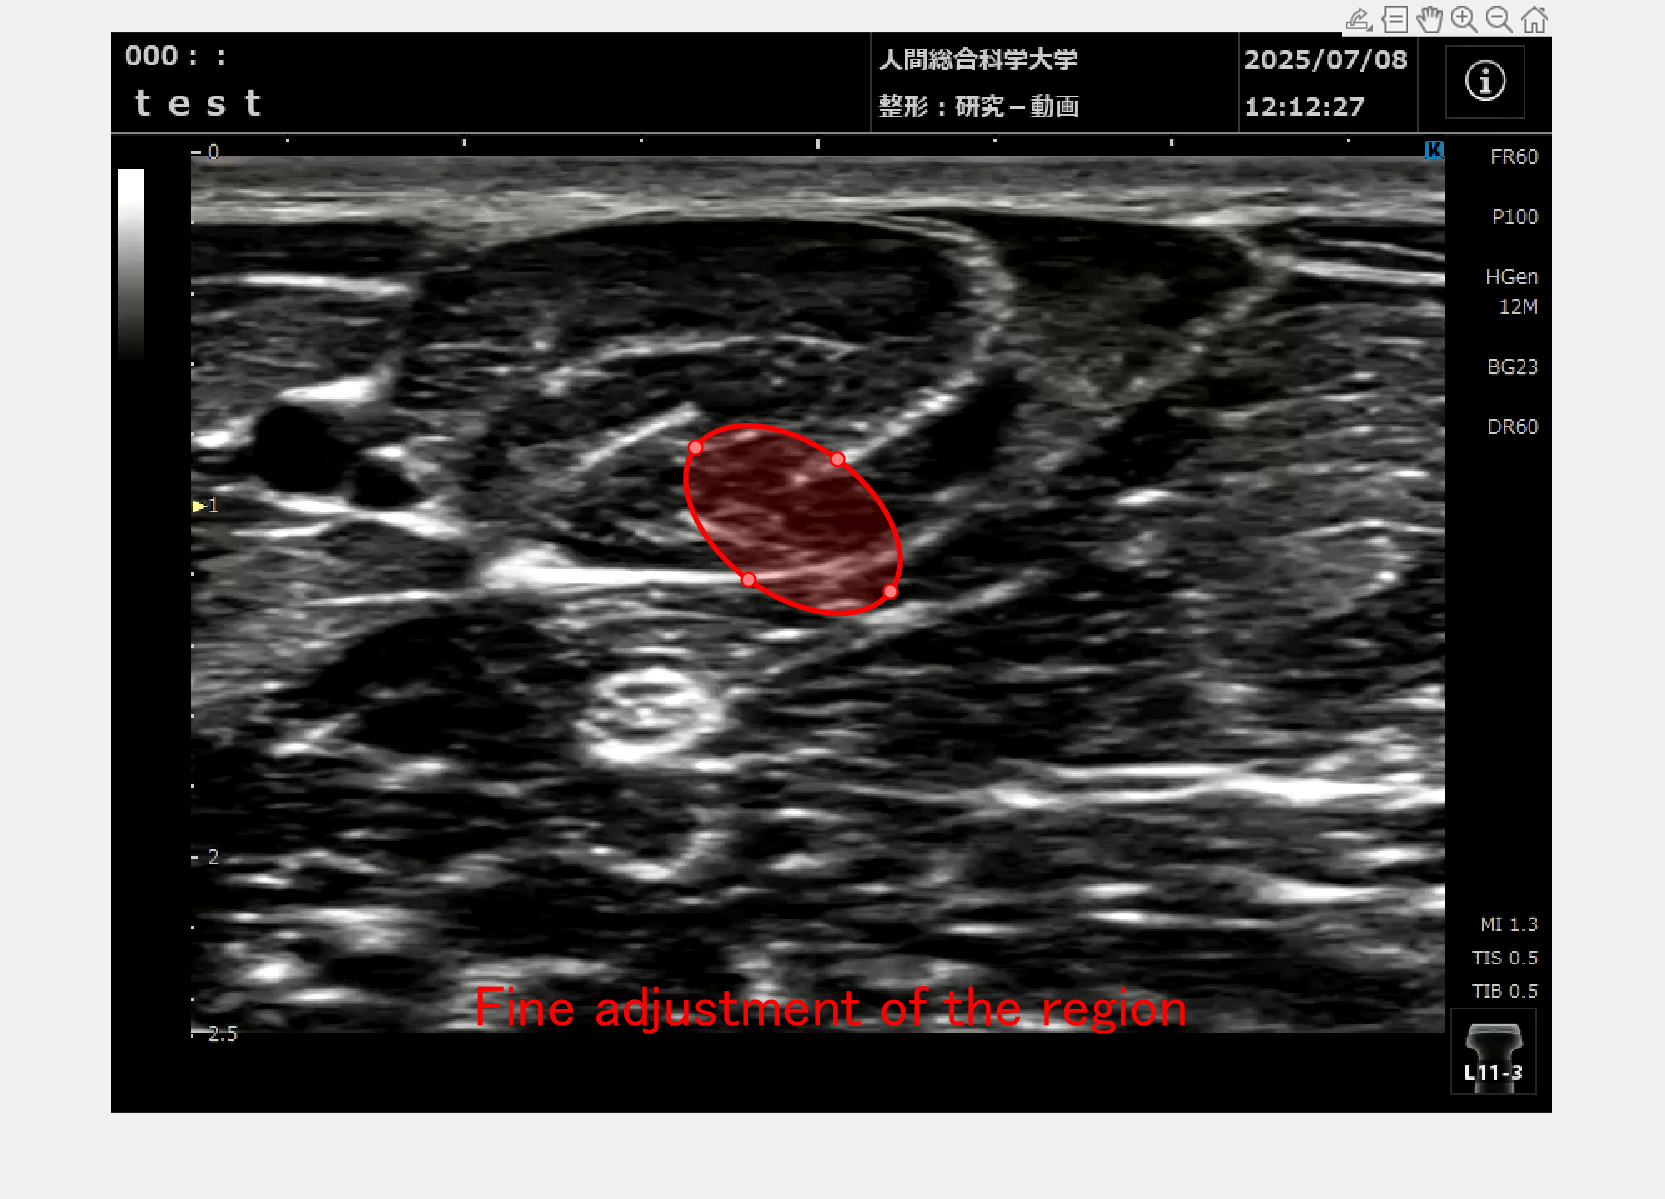

% Obtain current axis for placing instructions on the screen
ax = gca;
centerX = round(ax.XLim(2)*0.5);
centerY = round(ax.YLim(2)*0.9);
leftX   = round(ax.XLim(2)*0.2);

% Display instructions
TEXT = {"Select the region of interest"};
T1 = text(centerX, centerY, TEXT, 'Color', 'red', 'FontSize', 25, 'HorizontalAlignment', 'center');

% User specifies ROI
BW = drawellipse('color', 'r', 'InteractionsAllowed', "all");

% Remove initial instruction
delete(T1)

% Update instruction
TEXT = {"Fine adjustment of the region"};
text(centerX, centerY, TEXT, 'Color', 'red', 'FontSize', 25, 'HorizontalAlignment', 'center');


% Wait until the user finishes adjusting (double-click)
wait(BW);

%% Crop the ROI
BW = createMask(BW, vFirst);

% Extract cropped region and boundary coordinates
[Y,X] = find(BW);
Xleft  = min(X);  Xright = max(X);
Ylow   = min(Y);  Yup    = max(Y);

ht = Ylow:Yup;
wd = Xleft:Xright;

% Define ROI bounding box
bbox = [Xleft, Ylow, length(wd), length(ht)];
bboxPoints = bbox2points(bbox(1, :));

%% Feature detection (depends on ROI definition)
featurePoints = detectMinEigenFeatures(im2gray(vFirst).*uint8(BW), ...
    'ROI', bbox, 'MinQuality', 0.001);

% Feature point coordinates
Points = featurePoints.Location;

## movie output

%% Select output mode 
answer = questdlg('movie file', 'caution!!!', 'Writer','Non','~');


switch answer
    case 'Writer'
        Ans = 1;
    case 'Non'
        Ans = 2;
end

% Clear figure to avoid affecting video output
clf; close all

%% Create output video file
if Ans == 1
    v_out = VideoWriter(strcat('TrackElongation','_',sprintf(filename)), 'MPEG-4');
    v_out.FrameRate = FrameRate;
    open(v_out);
end

## Create pointTracker

% Define block size
bSize = round(size(vFirst,1)/15);

% Block size must be odd
if rem(bSize,2) == 0
    bSize = bSize + 1;
end

% Initialize tracker
pointTracker = vision.PointTracker('NumPyramidLevels', 5, ...
    'MaxBidirectionalError', inf, 'BlockSize', [bSize bSize], 'MaxIterations', 40);

initialize(pointTracker, Points, vFirst);

% Store initial points
oldPoints = Points;

%% Variables defined outside the loop to improve computation speed
analyzeRange = 1:videoReader.NumFrame;
lossIdx     = cell(1, length(analyzeRange));
trackPoint  = cell(1, length(analyzeRange));

## Start frame-by-frame analysis

video = read(videoReader);

for t = analyzeRange
    videoFrame = video(:,:,:,t);
    videoFrameFil = imfilter(videoFrame, h);

    [points, isFound, score] = step(pointTracker, videoFrameFil);

    % Remove outliers
    visiblePoints = points(isFound, :);
    oldInliers    = oldPoints(isFound, :);

    maxDis = size(vFirst,1)/43;
    [xform, inlierIdx] = estgeotform2d(oldInliers, visiblePoints, ...
        'similarity', 'MaxDistance', maxDis);

    oldInliers    = oldInliers(inlierIdx, :);
    visiblePoints = visiblePoints(inlierIdx, :);

    % Store indices of lost feature points
    lossIdx{t}   = findLossIdx(isFound, inlierIdx);
    trackPoint{t} = visiblePoints;

    % Update tracker
    oldPoints = visiblePoints;
    setPoints(pointTracker, oldPoints);

    FPnumber(t) = length(visiblePoints);
end


## Remove lost feature points and retain only those that survived until the final frame

% Number of feature points over time
Lfirst = cellfun(@length, trackPoint);

% Identify frames where the number of feature points changes
change = Lfirst(1:end-1) - Lfirst(2:end);
change = find(change > 0);
change = [0, change];

% Case where no feature points were lost
if change == 0
    FeaturePoint = cell2mat(trackPoint);

else  % Case where some feature points were lost during tracking
    
    % Extract frames before the first feature loss
    imgPreFrame = trackPoint(1, change(1)+1:change(2));
    imgPreFrame = cell2mat(imgPreFrame);

    % Remove lost points using lossIdx
    imgPreFrame(lossIdx{change(2)+1}, :) = [];

    % Process subsequent losses
    for i = 3:length(change)
        
        % Load frames before next reduction of feature points
        imgOld_ = trackPoint(1, change(i-1)+1:change(i));
        img = cell2mat(imgOld_);

        % Concatenate previous and current frames
        imgOld = [imgPreFrame, img];

        % Remove lost feature points
        LossIdx = lossIdx{change(i)+1};
        imgOld(LossIdx, :) = [];

        % Update reference for next iteration
        imgPreFrame = imgOld;
    end

    % Append final frames (no loss occurs in the last segment)
    lastFrame = trackPoint(1, change(end)+1:length(Lfirst));
    lastFrame = cell2mat(lastFrame);

    FeaturePoint = [imgPreFrame, lastFrame];
end


## Strain computation and video generation

% Get video resolution
frameWidth  = videoReader.Width;
frameHeight = videoReader.Height;

% Prepare off-screen figure for rendering
fig = figure('Visible','off');
ax = axes('Parent', fig);

for frame = analyzeRange

    % Extract feature point coordinates
    x = double(FeaturePoint(:, frame*2-1));
    y = double(FeaturePoint(:, frame*2));

    % Perform PCA to obtain principal strain direction
    [coeff, score, latent, ~, ~, mu] = pca([x, y]);

    % First principal component: longitudinal strain direction
    vFirst  = coeff(:,1);

    % Second principal component: transverse direction
    vSecond = coeff(:,2);

    % Project all feature points onto the first principal axis
    projectionFirst = ([x, y] - mu) * vFirst;

    %% Micro-strain estimation using feature-point spacing
    projectionAscFirst = sort(projectionFirst, 'ascend');

    % Distance between neighboring projected points
    dis_leftFirst  = projectionAscFirst(3:end)   - projectionAscFirst(2:end-1);
    dis_rightFirst = projectionAscFirst(2:end-1) - projectionAscFirst(1:end-2);

    % Mean inter-point distance
    disFirst = mean([dis_rightFirst, dis_leftFirst], 'all');

    % Store as time-series data
    disTSfirst(frame) = disFirst;

    %% Video rendering
    if Ans == 1
        videoFrame = video(:,:,:,frame);

        % Draw tracked feature points
        videoFrame = insertMarker(videoFrame, [x, y], "+", 'Color', 'yellow', 'Size', 6);

        % Compute center of feature points
        center = mean([x, y]);

        % Initialize reference length at first frame
        if frame == 1
            initialLFirst = projectionAscFirst(end) - projectionAscFirst(1);
        end

        % Update length based on strain
        Lfirst = initialLFirst * (disFirst / disTSfirst(1));

        % Angle of principal axis relative to horizontal
        thetaFirst = atan(vFirst(2) / vFirst(1));

        % Compute endpoints of principal axis line
        x1First = center(1) - (Lfirst/2) * cos(thetaFirst);
        x2First = center(1) + (Lfirst/2) * cos(thetaFirst);

        y1First = (vFirst(2)/vFirst(1)) * (center(1) - x2First) + center(2);
        y2First = (vFirst(2)/vFirst(1)) * (x2First - center(1)) + center(2);

        LinePCAfirst = [x1First, y1First, x2First, y2First];

        % Draw principal axis
        videoFrame = insertShape(videoFrame, "line", LinePCAfirst, ...
                                 'Color', 'green', "LineWidth", 8);

        % Write frame
        writeVideo(v_out, videoFrame);
    end
end

%% Convert strain to relative change from initial state
timeSeriesStrain = (disTSfirst - disTSfirst(1)) / disTSfirst(1);


## Save video file and MAT file

% Create directory for results
resultDir = fullfile(videoDir, 'Results');
if ~exist(resultDir, 'dir')
    mkdir(resultDir)
end

if Ans == 1
    close(v_out);
    movefile("TrackElongation_*", resultDir);
end

% Save computed variables
results.timeSeriesStrain = timeSeriesStrain;

% Save MAT file
cd(resultDir)
save("results.mat", "results");

toc

経過時間は 1991.996382 秒です。
